# Modulación FM

Autor(a): Luis Tomás García Andrade, Instituto Tecnológico de Tuxtla Gutiérrez, Departamento de Ingeniería Eléctrica y Electrónica

## Resumen

Los estudiantes diseñarán un modulador de frecuencia modulada, con la  ayuda de Matlab graficarán las señales moduladora, portadora, modulada y la respuesta a la frecuencia de las mismas

Palabras Clave: Modulación, portadora, respuesta en frecuencia.

## Objetivos de Aprendizaje

El objetivo principal de esta actividad es comprobar y evaluar diseño de un modulador de FM.

Para hacer la comprobación y evaluación del modulador los estudiantes realizarán las gráficas en Matlab de las señales moduladora, portadora y modulada con los datos del modulador diseñado.

Las gráficas obtenidas de Matlab se deben comparar con las obtenidas  de los instrumentos de medición de laboratorio del simulador de  circuitos.

Con los datos obtenidos de las gráficas de Matlab y de los  instrumentos de medición determinar si el prototipo cumple con las  especificaciones de diseño.

## Antes de empezar 

Este cuaderno computacional en MATLAB, o Live Script está diseñado para usarse con el código visible y mostrando los resultados en el cuaderno. En la pestaña **View** de las opciones de MATLAB (Toolstrip), en la sección **View**, seleccione **Output Inline**. De forma alternativa, seleccione **Output inline **usando el ícono  en la esquina derecha del editor del Live Script. 

 Interactuar con este Live Script le permitirá familiarizarse con MATLAB a medida que se introducen conceptos y comandos juntos. Si necesita más entrenamiento, considere realizar el curso [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), un tutorial en línea de 2 horas que enseña los conceptos básicos de MATLAB. 

   Para una experiencia óptima, siga las instrucciones y pasos en la secuencia indicada. Pase a una nueva sección sólo después de completar la anterior. Algunas secciones dependen de variables creadas en secciones anteriores y generarán errores si se ejecutan en desorden.

En este cuaderno tendrá la oportunidad de explorar la visualización de conceptos introducidos, pero también podrá usar ejercicios que le permitirán interactuar con el código y desafiar su comprensión de esos conceptos y su profesor puede usarlas para calificar y verificar la finalización.

## Sección 1: Conceptos 

Declaración de variables para la construcción de las señales

t = -0.04:1.e-4:0.04;
Ta = 0.01;
fc = 180;                                                           
msg = msg1(t,Ta);  

## Sección 2: Generación de la señal portadora

En esta sección adicione actividades que le permitan al estudiante practicar lo aprendido

porta=cos(2*fc*pi*t);

## Sección 3: Generación de la señal moduladora

En esta sección adicione actividades que le permitan al estudiante practicar lo aprendido

kf = 160*pi;
m_int = kf*1.e-4*cumsum(msg);             
fm = cos(2*fc*pi*t + m_int);  

## Sección 4: Demodulación (Usando diff)

dem = diff(fm);                 
dem = [0,dem];
rect_dem = abs(dem);

## Sección 5: Filtrado de frecuencias altas

N = 80;                                                            
Wn = 1.e-2;                                                   
a = fir1(N,Wn);                                             
b = 1;                                                               
rec = filter(a,b,rect_dem);

## Sección 6: Respuesta a la frecuencia de las señales con la transformada rápida de fourier

fl = length(t);
fl = 2^ceil(log2(fl));
f = (-fl/2:fl/2-1)/(fl*1.e-4);

mF = fftshift(fft(msg,fl));               
                                        
fmF = fftshift(fft(fm,fl));             

rect_demF = fftshift(fft(rect_dem,fl)); 

recF = fftshift(fft(rec,fl));  

## Sección 7: Trazado de las señales en el dominio del tiempo

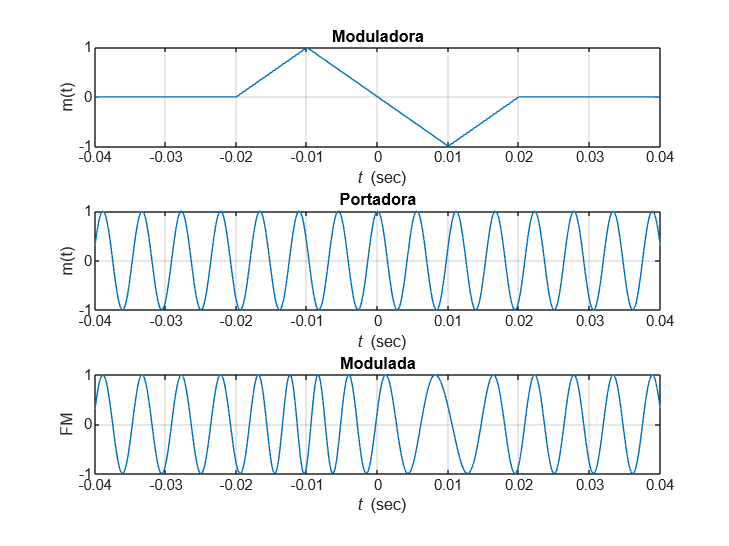

figure;
subplot(3,1,1)
plot(t,msg);
title('Moduladora');
xlabel('{\it t} (sec)');
ylabel('m(t)');
grid;

subplot(3,1,2)
plot(t,porta);
title('Portadora');
xlabel('{\it t} (sec)');
ylabel('m(t)');
grid;

subplot(3,1,3)
plot(t,fm);
title('Modulada');
xlabel('{\it t} (sec)');
ylabel('FM');
grid;

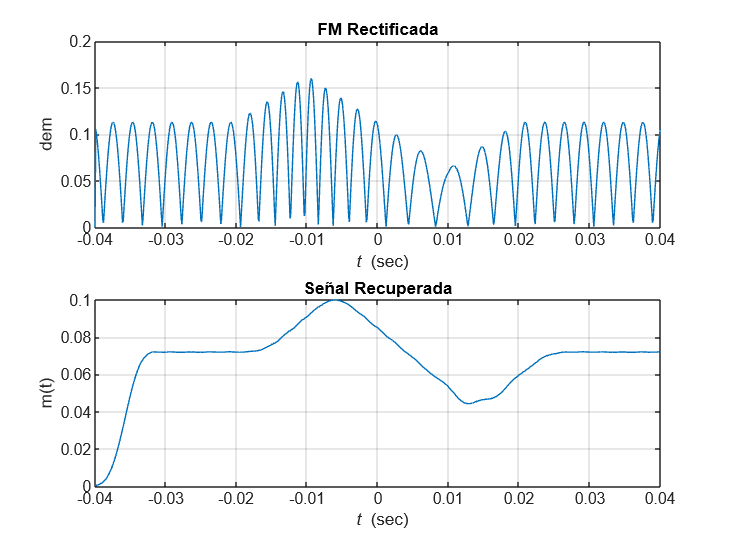


figure;
subplot(2,1,1);
plot(t,rect_dem);
title('FM Rectificada');
xlabel('{\it t} (sec)');
ylabel('dem')
grid;

subplot(2,1,2);
plot(t,rec);
title('Señal Recuperada');
xlabel('{\it t} (sec)');
ylabel('m(t)');
grid;

## Sección 8: Trazado de la respuesta a la frecuencia de las señales

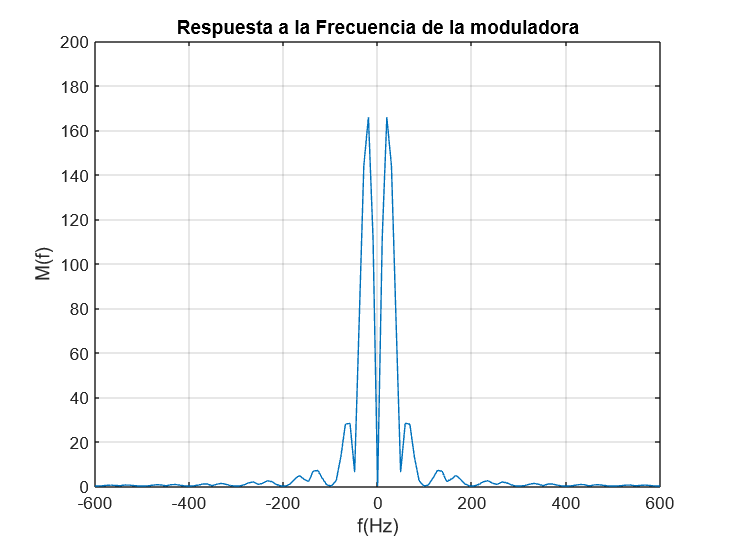

figure;
plot(f,abs(mF));
title('Respuesta a la Frecuencia de la moduladora');
xlabel('f(Hz)');
ylabel('M(f)');
grid;
axis([-600 600 0 200]);

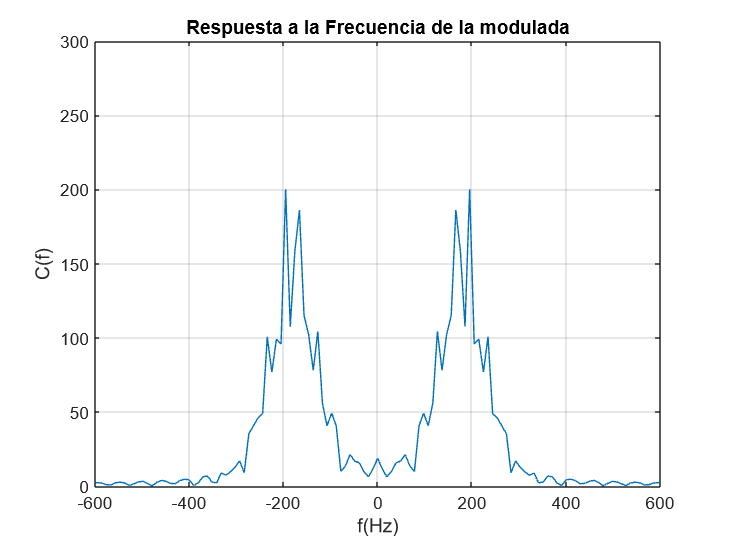


figure;
plot(f,abs(fmF));
title('Respuesta a la Frecuencia de la modulada');
grid;
xlabel('f(Hz)');
ylabel('C(f)');
axis([-600 600 0 300]);

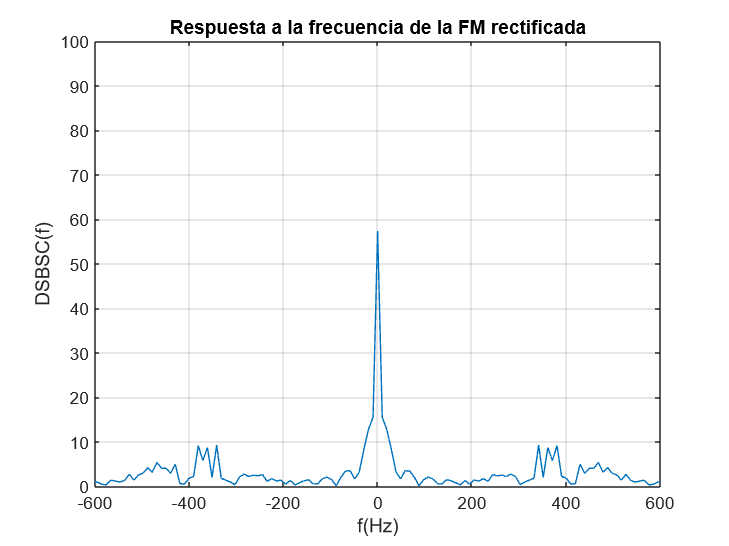


figure;
plot(f,abs(rect_demF));
title('Respuesta a la frecuencia de la FM rectificada');
xlabel('f(Hz)');
ylabel('DSBSC(f)');
grid;
axis([-600 600 0 100]);

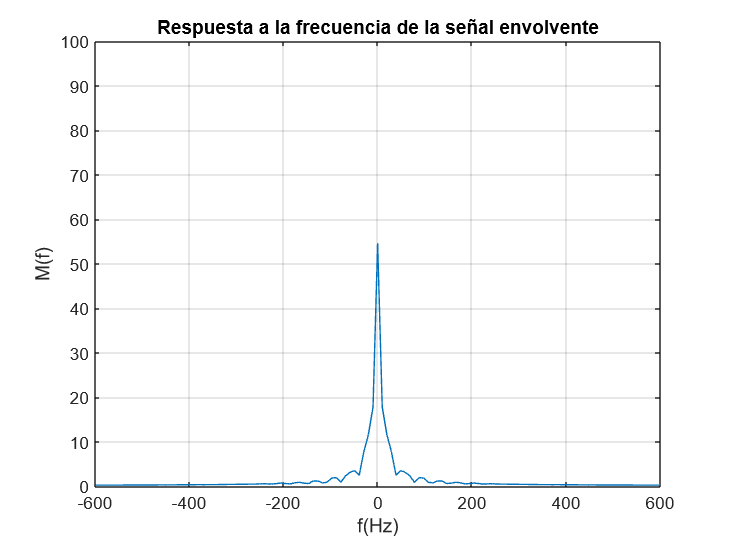


figure
plot(f,abs(recF));
title('Respuesta a la frecuencia de la señal envolvente');
xlabel('f(Hz)');
ylabel('M(f)');
grid;
axis([-600 600 0 100]);

## Recursos Adicionales

- Tomasi W. (2003). Cap 6 Transmisión por modulación angular. En Sistemas de comunicaciones electrónicas (pp 228 - 272). México. Pearson Educación.

- Lathi B.P. (2001). Cap 4 Sistemas de comunicación: modulación angular. En Introducción a la teoría y sistemas de comunicación. México, D.F. Editorial LIMUSA S.A. de C.V.

## Referencias 

- FM.m Copyright (c) 2012, SHEIKH  MUKHTAR HUSSAIN All rights reserved.